##                                                             Robótica - Cinemática Direta

##                                                                   Lista 07 - Revisão P2

clear; clc;
import RoboticaBiblioteca.*

maoDireita()

--- Regra da mão Direita ---
     eixo x --- indicador
     eixo y --- meio
     eixo z --- dedão
----------------------------
ver palma da mão -> positivo
para z: < positivo | > negativo
para x: palma da mão pra cima - positivo | palma da mão pra baixo - negativo
para y: pistola pra baixo - positivo | pistola pra cima - negativo


**Exercício 1) Cinemática direta para o manipulador Stanford**

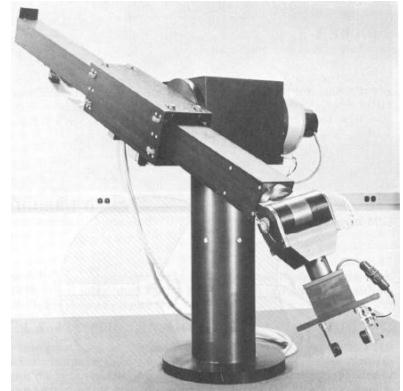

Características: Ele possui seis graus de liberdade, sendo os três primeiros no corpo do manipulador e os três últimos formando um punho esférico.

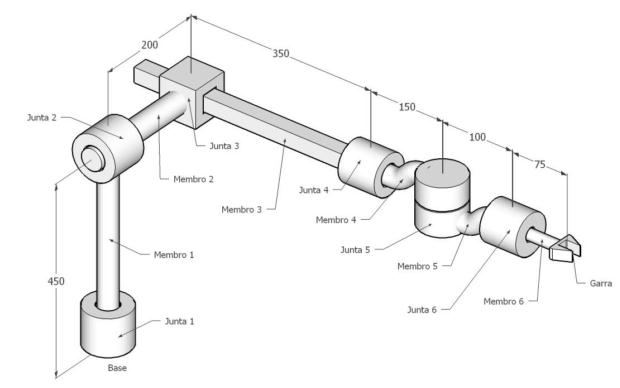

É importante destacar na anatomia deste manipulador a existência de um punho esférico, formado pelas últimas três juntas e pelos membros 4 e 5. A principal característica deste componente é que os eixos das juntas 4, 5 e 6 se interceptam em um único ponto (figura abaixo), chamado centro do punho.

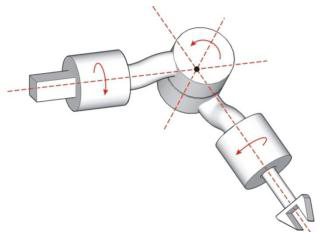

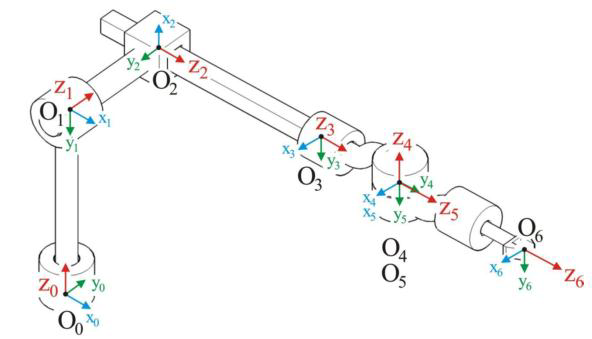

**Manipulador com todos os sistemas de coordenadas definidos**

Determine:

**a)** Parâmetros de Denavit-Hartenberg para o manipulador Stanford.

|  link  |   a   | alpha |    d    |      theta       |

| 0 - 1 |   0   |   -90   |  450  |    theta1*     |  R

| 1 - 2 |   0   |   -90   |  200  | theta2* - 90 |  R

| 2 - 3 |   0   |     0    |  350* |       +90        |  P

| 3 - 4 |   0   |  +90   |  150  |    theta4*      |  R }

| 4 - 5 |   0   |   -90   |    0    |    theta5*      |  R }  Punho esférico

| 5 - 6 |   0   |     0    |  175  |    theta6*      |  R }

**b)** Escrever uma matriz de transformação homogênea para cada junta

syms theta1 theta2 d3 theta4 theta5 theta6;
% denavit(theta, d, a, alpha)
A01 = denavit(theta1,450,0,-90)

$$A01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & 450\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = denavit(theta2-90,200,0,-90)

$$A12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}-90\right) & 0 & -\sin\left(\theta_{2}-90\right) & 0\\ \sin\left(\theta_{2}-90\right) & 0 & \cos\left(\theta_{2}-90\right) & 0\\ 0 & -1 & 0 & 200\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = denavit(+90,d3,0,0)

$$A23 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = denavit(theta4,150,0,+90)

$$A34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & 0 & \sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & 0 & -\cos\left(\theta_{4}\right) & 0\\ 0 & 1 & 0 & 150\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A45 = denavit(theta5,0,0,-90)

$$A45 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & 0 & -\sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & 0 & \cos\left(\theta_{5}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A56 = denavit(theta6,175,0,0)

$$A56 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & 175\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**c)** Encontrar a matriz de transformação homogênea total

A06 = A01*A12*A23*A34*A45*A56

% Compute simplified symbolic expression
simplifiedExpr = simplify(A06)

**d) **Determine a posição do órgão terminal para:

                                                                 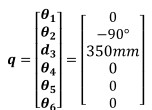

theta1 = 0;
theta2 = -90;
d3 = 350;
theta4 = 0;
theta5 = 0;
theta6 = 0;

A01 = denavit(theta1,450,0,-90);
A12 = denavit(theta2-90,200,0,-90);
A23 = denavit(+90,d3,0,0);
A34 = denavit(theta4,150,0,+90);
A45 = denavit(theta5,0,0,-90);
A56 = denavit(theta6,175,0,0);
A06 = A01*A12*A23*A34*A45*A56

A06 =            0           1           0           0
          -1           0           0         200
           0           0           1        1125
           0           0           0           1


**e) **Determine a posição do órgão terminal para:

                                                                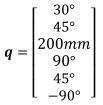

theta1 = 30;
theta2 = 45;
d3 = 200;
theta4 = 90;
theta5 = 45;
theta6 = -90;

A01 = denavit(theta1,450,0,-90);
A12 = denavit(theta2-90,200,0,-90);
A23 = denavit(+90,d3,0,0);
A34 = denavit(theta4,150,0,+90);
A45 = denavit(theta5,0,0,-90);
A56 = denavit(theta6,175,0,0);
A06 = A01*A12*A23*A34*A45*A56

A06 =     0.5000         0    0.8660  265.8848
   -0.8660         0    0.5000  384.4488
         0   -1.0000         0  202.5126
         0         0         0    1.0000


**f) **O Robô Esférico-Euler passe para Esférico-RAG:

Relembrar de fazer o desaclopamento

Separar H06 = H03 * H36

H36(1:3,1:3) --> Encontrar angulos de RAG

theta1 = 0;
theta2 = -90;
d3 = 350;
theta4 = 0;
theta5 = 0;
theta6 = 0;

A01 = denavit(theta1,450,0,-90);
A12 = denavit(theta2-90,200,0,-90);
A23 = denavit(+90,d3,0,0);
A34 = denavit(theta4,150,0,+90);
A45 = denavit(theta5,0,0,-90);
A56 = denavit(theta6,175,0,0);
A06 = A01*A12*A23*A34*A45*A56

A06 =            0           1           0           0
          -1           0           0         200
           0           0           1        1125
           0           0           0           1


pc = [A06(1,4); A06(2,4); A06(3,4)] - 75*[A06(1,1:3); A06(2,1:3); A06(3,1:3)]*[0; 0; 1]

pc =            0
         200
        1050


[r, beta, gamma] = movimentosTesf(pc(1),pc(2),pc(3));

r = NaN | beta = NaN | gamma = 90.000000


H03 = Tesf(r,beta,gamma)

H03 =    NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN


H03 = A01*A12*A23

H03 =      0     1     0     0
    -1     0     0   200
     0     0     1   800
     0     0     0     1


H36 = (H03)^-1 * A06

H36 =      1     0     0     0
     0     1     0     0
     0     0     1   325
     0     0     0     1


R36 = H36(1:3,1:3);
T36 = [R36, zeros(3,1);
       zeros(1,3), 1];
[thetaN, thetaO, thetaA] = angsRAG(T36);

ThetaN = 0.000000 | ThetaO = -0.000000 | ThetaA = 0.000000


confusao()

phi = thetaA
theta = thetaO
psi = thetaN


**Questão 2) **Determine a solução para a cinemática inversa de orientação para o manipulador cujos dados são apresentados abaixo

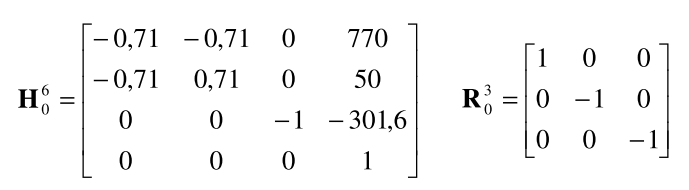

H06 = [-0.71 -0.71 0 770;
       -0.71 0.71 0 50;
       0 0 -1 -301.6;
       0 0 0 1];
R06 = H06(1:3,1:3)

R06 =    -0.7100   -0.7100         0
   -0.7100    0.7100         0
         0         0   -1.0000


R03 = [1 0 0;
       0 -1 0;
       0 0 -1];
R36 = (R03)^-1 * R06

R36 =    -0.7100   -0.7100         0
    0.7100   -0.7100         0
         0         0    1.0000


[thetaN, thetaO, thetaA] = angsRAG(R36);

ThetaN = 0.000000 | ThetaO = -0.000000 | ThetaA = 135.000000


[theta, phi_plus_psi] = angsEuler(R36);

theta = 0.000000 | phi + psi = 135.000000


**Questão 3) **Dadas as equações que definem a cinemática inversa de posição para o manipulador abaixo.

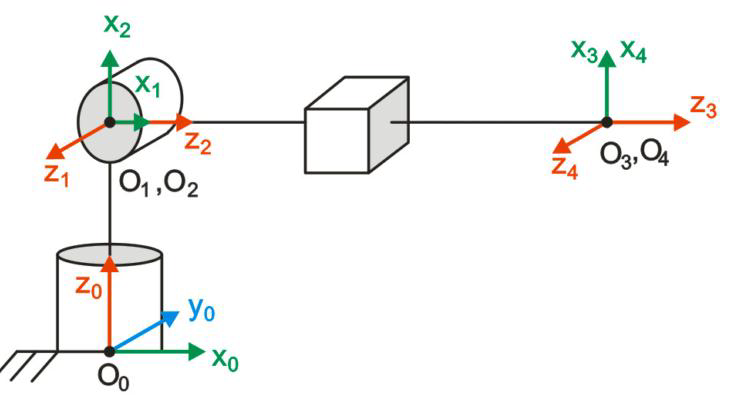

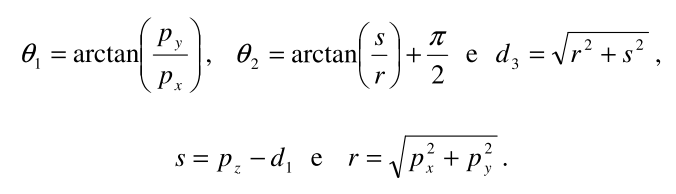

O manipulador possui os seguintes parâmetros de Denavit-Hartenberg e as seguintes coordenadas para o centro do punho,

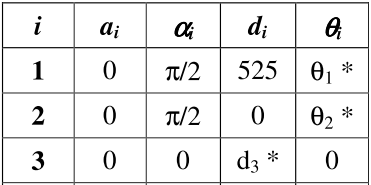                  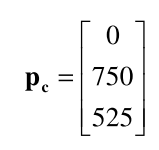

Determine as variáveis das juntas para a cinemática inversa de posição.

theta1 = atan2d(750,0)

theta1 = 90

s = 525 - 525

s = 0

r = sqrt(0^2 + 750^2)

r = 750

theta2 = atan2d(s,r) + 180/2

theta2 = 90

d3 = sqrt(s^2 + r^2)

d3 = 750

A01 = denavit(theta1,525,0,180/2);
A12 = denavit(theta2,0,0,180/2);
A23 = denavit(0,d3,0,0);
H03 = A01*A12*A23

H03 =      0     1     0     0
     0     0     1   750
     1     0     0   525
     0     0     0     1


**Questão 4)** Para piorar a situação foi anexado um punho esférico no manipulado em questão, tornando um manipulador de 6 DOF. Calcule a cinemática inversa de orientação, dada a seguinte matriz de transformação homogênea total:

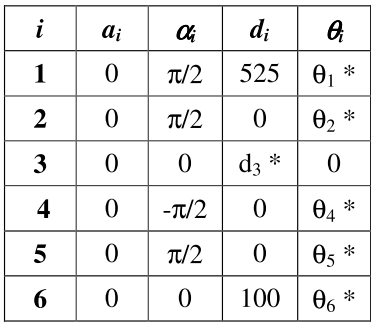              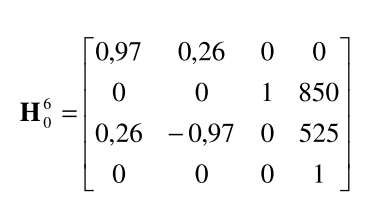

H06 = [0.97 0.26 0 0;
       0 0 1 850;
       0.26 -0.97 0 525;
       0 0 0 1];
H36 = (H03)^-1 * H06

H36 =     0.2600   -0.9700         0         0
    0.9700    0.2600         0         0
         0         0    1.0000  100.0000
         0         0         0    1.0000


[thetaN, thetaO, thetaA] = angsRAG(H36);

ThetaN = 0.000000 | ThetaO = -0.000000 | ThetaA = 74.995080


[theta, phi_plus_psi] = angsEuler(H36);

theta = 0.000000 | phi + psi = 74.995080
